clear all;
close all;
setenv('RMW_IMPLEMENTATION','rmw_fastrtps_cpp')
setenv('ROS_DOMAIN_ID','30')

%% --- Helper Functions ---

function [] = goalCallback(msg, goalHandle)
    % Update global goal pose from incoming goal message
    goalHandle.x = msg.pose.position.x;
    goalHandle.y = msg.pose.position.y;
    quat = [msg.pose.orientation.w, msg.pose.orientation.x, msg.pose.orientation.y, msg.pose.orientation.z];
    eul = quat2eul(quat);
    goalHandle.theta = eul(1);
    disp("Received new goal pose.");
end

function [x, y, theta] = OdometryMsg2Pose(poseMsg)
    % Convert odometry message to pose vector [x, y, theta]
    x = poseMsg.pose.pose.position.x;
    y = poseMsg.pose.pose.position.y;
    quat = [poseMsg.pose.pose.orientation.w, poseMsg.pose.pose.orientation.x, ...
            poseMsg.pose.pose.orientation.y, poseMsg.pose.pose.orientation.z];
    eul = quat2eul(quat);
    theta = eul(1);
end

function goalPose = goalHandle2goalPose(goalHandle,tfTree)
    pt = ros2message('geometry_msgs/PoseStamped');
    pt.header.frame_id = 'map';
    pt.pose.position.x = goalHandle.x;
    pt.pose.position.y = goalHandle.y;
    pt.pose.position.z = 0;
    quat = axang2quat([0 0 1 goalHandle.theta]);
    pt.pose.orientation.w = quat(1);
    pt.pose.orientation.x = quat(2);
    pt.pose.orientation.y = quat(3);
    pt.pose.orientation.z = quat(4);
    % goalPose = transform(tfTree,'odom',pt);
    if canTransform(tfTree,'odom','map')
        goalPose = transform(tfTree,'odom',pt);
    else
        goalPose = goalHandle;
    end
    % tform = getTransform(tfTree,"odom","map");
    % goalPose = rosApplyTransform(tform,pt);
    % goalPose = [goalHandle.x,goalHandle.y,goalHandle.theta];
end

## 1) Initiate MATLAB ROS 2 node (no rosinit needed)

params.use_sim_time = true;
matlabNode = ros2node("/maty", 30, Parameters=params);
%% 2) Create velocity publisher and odom subscriber
velPub = ros2publisher(matlabNode, '/cmd_vel', 'geometry_msgs/Twist');
odomSub = ros2subscriber(matlabNode, '/odom', 'nav_msgs/Odometry');
velMsg = ros2message(velPub);

disp('Publisher and odom subscriber created.');

%% 3) Create goal subscriber with callback to update global goal pose

goalHandle = PoseHandle();
goalSub = ros2subscriber(matlabNode, '/goal_pose', 'geometry_msgs/PoseStamped', ...
    @(msg) goalCallback(msg, goalHandle));

disp('Goal subscriber created.');

%% 4) Load map and visualize initial pose and goal

% Load and process map image
map_img = imread('rst_lab_cropped.pgm');
bwimage = map_img < 100;  % binary threshold for occupancy
bwimage = imrotate(bwimage, 90); % align map properly

% Create binary occupancy map with resolution 0.05 m/cell
map = binaryOccupancyMap(bwimage, 1/0.05);
map.GridLocationInWorld = [-4.5, -2.8];

figure("Name", "Map");
show(map);
hold on;


disp('Waiting for initial odometry and goal...');
pause(1);  % Wait for initial messages to arrive

% Receive initial odometry message
opose = receive(odomSub, 10);
[robot_x, robot_y, robot_theta] = OdometryMsg2Pose(opose);

% Plot robot initial pose
plot(robot_x, robot_y, 'go', 'MarkerSize', 8, 'DisplayName', 'Robot Pose');

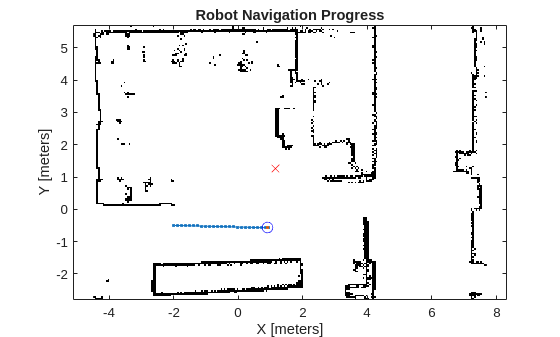


% Get transformation tree for goal pose
tfTree  = ros2tf(matlabNode);

pause(2);

% Transform goalHandle
% gpose = receive(goalSub, 10);
goalPose = goalHandle2goalPose(goalHandle,tfTree);

% Plot goal pose
plot(goalPose.pose.position.x, goalPose.pose.position.y, 'rx', 'MarkerSize', 8, 'DisplayName', 'Goal Pose');


% legend;


%% 5) Implement global planners (PRM or RRT)

global_planner = "RRT"; % or "PRM"

% Setup state space and validator
stateSpace = stateSpaceSE2;
stateSpace.StateBounds = [-4.5 4.5; -2.8 2.8; -pi pi];  % same as map extents

stateValidator = validatorOccupancyMap(stateSpace);
stateValidator.Map = map;
stateValidator.ValidationDistance = 0.01;

start_pose = [robot_x, robot_y, robot_theta];
goalQuat = [goalPose.pose.orientation.w, goalPose.pose.orientation.x, ...
            goalPose.pose.orientation.y, goalPose.pose.orientation.z];
eul = quat2eul(goalQuat);
goal_pose = [goalPose.pose.position.x, goalPose.pose.position.y, eul(1)];

switch global_planner
    case "PRM"
        disp("Executing PRM...");
        maxNumNodes = 250;

        planner = plannerPRM(stateSpace, stateValidator,"MaxNumNodes",maxNumNodes);

        % Visualize roadmap
        show(stateValidator.Map); hold on;

        graph = graphData(planner);
        nodes = table2array(graph.Nodes);
        edges = table2array(graph.Edges);

        % Draw nodes
        plot(nodes(:,1), nodes(:,2), '*b', 'LineWidth', 2);

        % Draw edges
        for i = 1:size(edges,1)
            n1 = edges(i,1);
            n2 = edges(i,2);
            seg = interpolate(stateSpace, nodes(n1,:), nodes(n2,:), 0:0.02:1);
            plot(seg(:,1), seg(:,2), 'b');
        end

        % Plot start and goal
        plot(start_pose(1), start_pose(2), '*g', 'LineWidth', 3);
        plot(goal_pose(1), goal_pose(2), '*r', 'LineWidth', 3);

        % Plan path
        [path, solnInfo] = plan(planner, start_pose, goal_pose);

        % Visualize path
        if solnInfo.IsPathFound
            plot(path.States(:,1), path.States(:,2), ...
                 'Color', [0.85 0.325 0.098], 'LineWidth', 2);
        else
            warning('PRM: Path not found');
        end
        hold off;
        plannedPath = path.States;

    case "RRT"
        disp("Executing RRT...");
        planner = plannerRRT(stateSpace, stateValidator);
        planner.MaxIterations = 500;
        planner.MaxConnectionDistance = 0.5;

        % Plan
        [path, solnInfo] = plan(planner, start_pose, goal_pose);

        % Visualize
        show(stateValidator.Map); hold on;
        plot(start_pose(1), start_pose(2), '*g', 'LineWidth', 3);
        plot(goal_pose(1), goal_pose(2), '*r', 'LineWidth', 3);

        % Tree visualization not supported in MATLAB plannerRRT
        % Just plot the resulting path
        if solnInfo.IsPathFound
            plot(path.States(:,1), path.States(:,2), 'r-', 'LineWidth', 2);
        else
            warning('RRT: Path not found');
        end

        plannedPath = path.States;

    otherwise
        error('Unknown global planner: %s', global_planner);
end

Executing RRT...


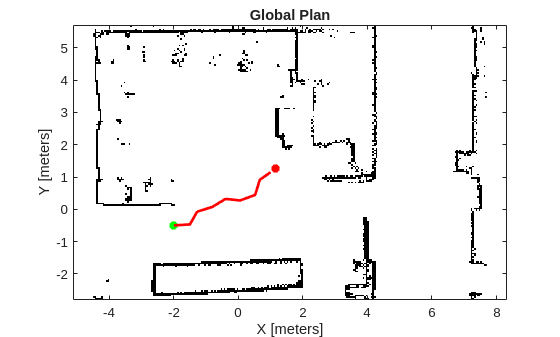


title('Global Plan');
axis equal;

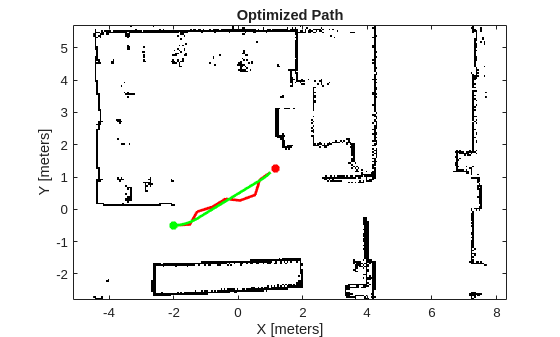

%% 6) Optimize the path using TEB (optimizePath function)

options = optimizePathOptions;
[optimizedPath, kineticInfo, solutionInfo] = optimizePath(plannedPath, options);

figure;
show(stateValidator.Map); hold on;
plot(start_pose(1), start_pose(2), '*g', 'LineWidth', 3);
plot(goal_pose(1), goal_pose(2), '*r', 'LineWidth', 3);
plot(plannedPath(:,1), plannedPath(:,2), 'r-', 'LineWidth', 2);
plot(optimizedPath(:,1), optimizedPath(:,2), 'g-', 'LineWidth', 2);
title('Optimized Path');
axis equal;

drawnow;

%% 7) Implement the TEB local planner to follow the path and avoid obstacles

% Initialize ControllerTEB with optimized path and map
teb = controllerTEB(optimizedPath, map);
teb.RobotInformation.Shape = "Rectangle";
teb.RobotInformation.Dimension = [0.2 0.2];
teb.LookAheadTime = 5.0;
teb.MaxVelocity = [0.5 1.5];
teb.MaxAcceleration = [0.5 0.5];
teb.ReferenceDeltaTime = 0.3;
teb.ObstacleSafetyMargin = 0.1;
teb.MinTurningRadius = 0.0;
teb.MaxReverseVelocity = 0.0;

rate = robotics.Rate(5);  % 5 Hz update rate
goalReached = false;

% Initialize current velocity and pose
curvel = [0 0 0];

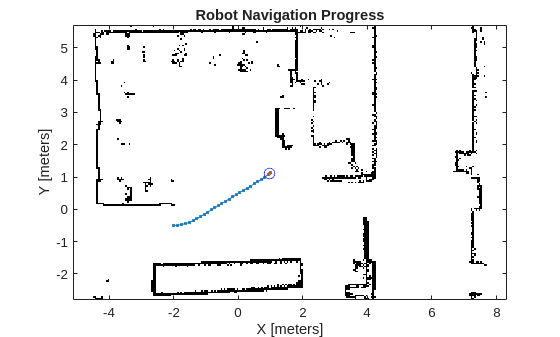


while ~goalReached
    % Update current pose from odometry
    opose = receive(odomSub, 1);
    [cur_x, cur_y, cur_theta] = OdometryMsg2Pose(opose);

    vx = opose.twist.twist.linear.x;      % Forward velocity (m/s)
    omega = opose.twist.twist.angular.z;  % Rotational velocity (rad/s)

    % Combine into velocity vector
    curvel = [vx, omega];

    % curvel = teb.CurrentVelocity;

    % Compute velocity commands from TEB
    [velcmds, ~, curpath, info] = step(teb, [cur_x, cur_y, cur_theta], curvel);

    goalReached = info.HasReachedGoal;

    % Visualization
    clf;
    show(map); hold on;
    plot(optimizedPath(:,1), optimizedPath(:,2), '.-');
    plot(curpath(:,1), curpath(:,2), '.-');
    plot(cur_x, cur_y, 'bo', 'MarkerSize', 8);
    title('Robot Navigation Progress');
    axis equal;
    drawnow;

    % Publish velocity commands
    velMsg.linear.x = velcmds(1,1);
    velMsg.angular.z = velcmds(1,2);
    send(velPub, velMsg);

    % fprintf('\rLast Linear Velocity: %.2f m/s | Last Angular Velocity: %.2f rad/s', vx, omega);
    % fprintf('\rPub Linear Velocity: %.2f m/s | Pub Angular Velocity: %.2f rad/s', velcmds(1), velcmds(3));

    waitfor(rate);
end


disp('Goal reached.');

Goal reached.
